# **Tutorial: 1D Linear Static Spring-Mass system**

 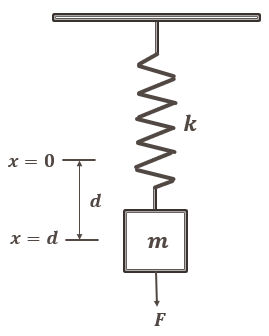

Figure 1: Schematic diagram of a static spring-mass system.

We have a simple linear static spring-mass system whose spring has a constant stiffness, $k$. With a known displacement, $ d$, we want to estimate the value of the stiffness, $k$, through measuring its restoring force, $F$, which obeys the following equation model: 


$$F= - k \cdot  d$$


In this problem, the model is assumed to be perfect but the measurements, $F_{noisy}$, are affected by noise, $\epsilon$, whereby: 


$$F_{noisy}= -k \cdot d + \epsilon$$


This problem is often referred in literature as model updating which is an inverse problem whereby the parameter of interest (in this case, $k$) is being calculated based on the measurements of observations (in this case, $F_{noisy}$) that is made from the system of interest. In other words, the model input is being calculated from the model output contrary to the forward problem where the model output is being calculated from a set of known model input(s).

### Problem Statement:

In this problem, we will compare the performances of the MCMC, TMCMC, and the SMC sampler in the estimation of the parameter, $k$. This comparion will be made under a common criteria of attaining COV, $\alpha$, of 2.0 %. This COV, $\alpha$, is defined as:


$$\alpha = \frac{\sigma}{\mu} \times 100 \%$$


whereby $\sigma$ is the standard deviation of the estimate, and $\mu$ is the mean of the estimate. As such, the comparison of the performance of the 3 samplers in attaining this convergence criteria of 2.0 % Percentage error, will be made on the basis of sample size required to achieve the criteria, the time-elapsed for the samplers to achieve this, and the closeness of the mean to the true value of $k$. 

## 1) Observations

We assume $15$ independent observations of the model are available. The real value of $k$ is unknown to the analyst. The observations are also collected for random values of displacement, $ d$, between $0.02$ and $0.08$ metres.

% True value of k [N/m]:  
ndims = 1; % number of unknown parameters to be estimated
k = 263;

% Number of observations:
Nobservations = 15;   

% Generate 15 random displacements between 0.02 and 0.08 meters [m]:
displacements = unifrnd(0.02,0.08,Nobservations,1);

It is also assumed that the observations, $ F_{noisy}$, are corrupted with noise, $\epsilon$. In this problem, $\epsilon$ is modelled as Normal distribution with mean $0$ N and standard deviation $1$ N. 

The Model function is also defined as a handle function. Details to the function can be found in the file titled: "model.m".

% Standard deviation of the noise [N]:
NoiseStandardDeviation = 1; 

% Defining the Noise associated with the Measurements [N]:
MeasurementsNoise = randn(Nobservations,1)*NoiseStandardDeviation;

% Defining the Measurement function handle without Noise [N]:
MyModel = @(x,y) model(x,y);

% Defining the Measurement corrupted with Noise [N]:
Measurements = MyModel(k,displacements) + MeasurementsNoise;

These measurements are plotted in a scatter plot.

% To plot the scatter plot of the measurements:
figure;
x_err = 0.003.*ones(15,1);
y_err = ones(15,1);
h1 = errorbar(displacements,Measurements,y_err,y_err,x_err,x_err,'o','LineWidth',0.8)

h1 =   ErrorBar with properties:

             Color: [0 0.4470 0.7410]
         LineStyle: 'none'
         LineWidth: 0.8000
            Marker: 'o'
             XData: [0.0689 0.0743 0.0276 0.0748 0.0579 0.0259 0.0367 0.0528 0.0775 0.0779 0.0295 0.0782 0.0774 0.0491 0.0680]
             YData: [-18.3213 -19.6775 -5.7742 -18.2640 -13.8214 -6.1277 -10.8622 -13.1726 -18.7392 -19.9970 -6.7124 -19.8491 -20.6675 -12.6254 -18.6757]
    XNegativeDelta: [0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030]
    XPositiveDelta: [0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030]
    YNegativeDelta: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
    YPositiveDelta: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]

  Show 

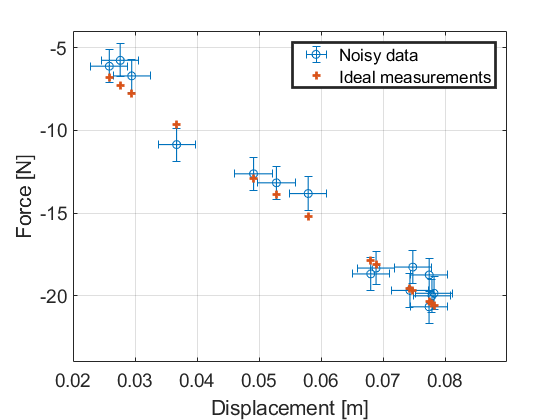

hold on
grid on
h2 = scatter(displacements,MyModel(k,displacements),'LineWidth',2,'Marker',"+");
xlim([0.02 0.09])
ylim([-24 -4])
xlabel('Displacement [m]','FontSize',14)
ylabel('Force [N]','FontSize',14)

% To customize the figure:
h=gca;
h.Box='on';
h.FontSize=14;
legend(h,'Noisy data','Ideal measurements','LineWidth',2)

## 2) Least-squares solution

### 2.1) Calculating the Least-squares solution of $k$

One direct method through which this problem can be solved is via Linear Least-squares minimization. 

The Least-squares solution to the problem is in general a vector of unknown parameter to be estimated. The normal equations are given by


$$(x^T x) k = x^T F$$


where x' is the transpose of the design matrix *x*. Solving for *k:*


$$k = (x^T x)^{-1} x^T F$$


Use the backslash operator \ ([`mldivide`](https://uk.mathworks.com/help/matlab/ref/mldivide.html)) to solve a system of simultaneous linear equations for unknown coefficients.

% Calculating the Least squares of k:
kleastsquare = - displacements\Measurements;

% Calculating the Least squares error of k:
errors_leastSquare = ((kleastsquare-k)/k)*100;

% Print and display the results for the Least squares error of k:
sprintf('Error least square: %f%%',errors_leastSquare)

ans = 'Error least square: -2.709249%'

### 2.2) Plot results from the least squares method

% Calculate results from the model:
disp=linspace(0,0.1,50);
Fleastsquares = MyModel(kleastsquare,disp);
True_model = MyModel(k,disp);
figure;
h1 = errorbar(displacements,Measurements,y_err,y_err,x_err,x_err,'o','LineWidth',0.8)

h1 =   ErrorBar with properties:

             Color: [0 0.4470 0.7410]
         LineStyle: 'none'
         LineWidth: 0.8000
            Marker: 'o'
             XData: [0.0689 0.0743 0.0276 0.0748 0.0579 0.0259 0.0367 0.0528 0.0775 0.0779 0.0295 0.0782 0.0774 0.0491 0.0680]
             YData: [-18.3213 -19.6775 -5.7742 -18.2640 -13.8214 -6.1277 -10.8622 -13.1726 -18.7392 -19.9970 -6.7124 -19.8491 -20.6675 -12.6254 -18.6757]
    XNegativeDelta: [0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030]
    XPositiveDelta: [0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030 0.0030]
    YNegativeDelta: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
    YPositiveDelta: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]

  Show 

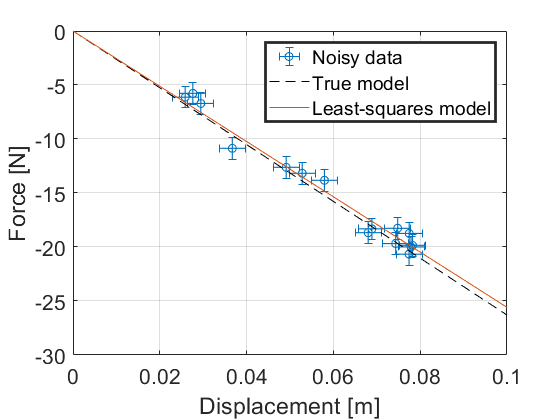

box on
grid on
hold on
plot(disp,True_model,'k--')
plot(disp,Fleastsquares)
legend('Noisy data','True model','Least-squares model','LineWidth',2)
xlabel('Displacement [m]','FontSize',16)
ylabel('Force [N]','FontSize',16)
set(gca,'FontSize',16)
hold off

## 3) Bayesian Model Updating

Bayesian Model Updating is a form of model updating based on Bayesian Inference. The parameters of interest are treated as random variables with a joint Probability distribution function associated with them. Bayesian Inference devises a joint Probability distribution function for the parameters based on prior information about the distribution and observations (evidence). 

The Bayesian Inference framework is based upon the well-known Bayes Rule:


$$P(\mathbf{\theta}|D) = \frac{P(D|\mathbf{\theta})\cdot P(\mathbf{\theta})}{P(D)}$$


whereby $\mathbf{\theta}$ is a vector of the parameter(s) to be estimated, $D$ is defined to be the measurements or observations made form the system, $P(\mathbf{\theta})$is defined as the Prior distribution, $P(D|\mathbf{\theta})$ is defined as the Likelihood function, $P(\mathbf{\theta}|D)$ is defined as the posterior distribution, and $P(D)$ is defined as the Evidence and is also the normalisation constant of the posterior distribution. 

In the context of this problem, $\mathbf{\theta}$ would be our stiffness parameter, $k$, we wish to estimate. $D$ are the set of measurements or observations which in this case would be the Force, ${F}$.

The samplers presented in this tutorial construct the un-normalised posterior distribution through the direct product of the prior and likelihood distributions: 

    
$$P(\mathbf{\theta}|D) \propto P(D|\mathbf{\theta}) \cdot P(\mathbf{\theta})$$


The components of the Bayesian Model updating are passed as handle functions.

### 3.1) Define Prior distribution

The Prior distribution, $P(\mathbf{\theta})$, is a reflection of one’s a priori knowledge or initial hypothesis about the model’s parameter(s), $\mathbf{\theta}$, before any observations or measurements are being made. For instance, if what is known initially about $\mathbf{\theta}$ is/are its upper and lower bounds, a Uniform distribution about these two bounds can be used to model the hypothesis. If what is known initially about $\mathbf{\theta}$ is/are its mean value(s) with the associated errors, a Normal distribution could be used to model that hypothesis.

We model out Prior knowledge of $k$ based on the initial hypothesis that $k$ can range between $1$ N/m to $1000 $ N/m.  As such, we will model this non-informative Prior which by a Uniform Distribution with an lower bound of $1$ N/m and an upper bound of $1000 $ N/m.

% Define parameters:
lowerBound = 1;    % [N/m]
upperBound = 1000; % [N/m]

% Prior distribution function for k:
prior_pdf = @(x) unifpdf(x,lowerBound,upperBound);

% Define sample rules function for the Prior:
rnd_k = @(N) unifrnd(lowerBound,upperBound,N,ndims); 

% NOTE ON ANONYMOUS FUNCTION:
% The (fix) parameters in the anonymous functions are defined at the moment
% of the function declaration. For instance, lowerBound and upperBound are
% now costants fixed for prior_pdf, logprior and rnd_k.

### 3.2) Define Likelihood Function

The Likelihood function, $P (D|\mathbf{\theta} )$, is a function which reflects the degree of agreement between the measurement and the system's model. We define the Likelihood function to follow a Normal distribution and assuming independence between the 15 observations of $ F_{noisy}$ made, the Likelihood function $P (D|\mathbf{\theta} )$can be expressed as such:


$$P(D|\mathbf{\theta}) \propto \prod^{N}_{j=1} exp \left[-\frac{1}{2 \cdot \sigma_j^2}(D_j - k \cdot d_j)^2 \right]$$


whereby $D_j$ represents the $j^{th}$ observation made of $\vec F_{noisy}$, $d_j $ represents the $j^{th}$ observation made of the displacement, and $\sigma_j$ represents the standard deviation of the Likelihood function associated with the $j^{th}$ observation and$N$ denotes the number of observations. The standard deviation, $\sigma_{j}$, is a hyperparameter and a choice of value of $\sigma_{j}$ would be to set it as a constant equal to the standard deviation of the noise $\epsilon$ (if known) or as an additional parameter to be identified. 

In order to improve the stability of the code, a Loglikelihood is adopted. In the Logarithmic space, the Loglikelihood function, $log(P (D|\mathbf{\theta}) )$, is expressed as such:


$$log(P(D|\mathbf{\theta})) \propto \sum^{N}_{j=1} -\frac{1}{2 \cdot \sigma^2_j}(D_j -k \cdot d_j)^2$$


The Loglikelihood function is also defined as a handle function. Details to the function can be found in the file titled: "log_likelihood.m".

% Defining the Log Likelihood distribution function:
log_l = @(theta) log_likelihood(theta,displacements,Measurements,NoiseStandardDeviation,MyModel); 

### 3.3) Define Posterior Distribution

The Posterior distribution, $P(\mathbf{\theta}|D)$, represents the updated knowledge and our degree of uncertainty about the parameter(s) $\mathbf{\theta}$ after taking into account the observations and the measurements made. 

The Posterior distribution is defined in the Log-space and the Logposterior function is defined as follows:


$$log(P(\mathbf{\theta}|D)) \propto log(P(D|\mathbf{\theta})) + log(P(\mathbf{\theta}))$$


whereby $log(P (D|\mathbf{\theta}) )$ is the Loglikelihood function, and $log(P (\mathbf{\theta}) )$ is the Logprior function.

The Logposterior function is also defined as a function handle.

% Defining the Posterior distribution function in Log space:
target_PDF = @(theta) log(prior_pdf(theta)) + log_l(theta); 

## 4)  The samplers

### 4.1) Markov Chain Monte Carlo (MCMC)

The MCMC sampling method is a method which can be adopted to sample from a Target distribution without the need to know the entire mathematical properties of the distribution such as its normalisation constant in this case. The MCMC sampler itself utilises two properties: Monte-Carlo and Markov Chain. 

The MCMC sampler adopts the standard implementation of the MCMC algorithm in the form of the [Metropolis-Hastings](https://academic.oup.com/biomet/article/57/1/97/284580) algorithm. Details to the algorithm can be found in Algorithm 1 of the tutorial paper.

To initiate the sampler, there are 5 parameters that need to be defined: the number of samples to obtain from the Posterior distribution (Nsamples_mcmc), the Tuning-parameter (Tuning_mcmc), Burn-in (BurnIn), the Number of Chains (NumberOfChains), and the starting value of the Chain (Start). 

The number of samples (Nsamples_mcmc) parameter defines the sample size to be obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$.

The Tuning parameter (Tuning_mcmc) for the MCMC sampler corresponds to the standard deviation of the Proposal distribution (which will be explained in Section 4.1.1) that is used in this MCMC sampler to generate Proposed samples. The choice of the tuning paramater determines the acceptance rate of the Proposed samples, thereby, determining the performance of the MCMC sampler. As a guide, the optimal choice of the tuning parameter is one which gives rise to an acceptance rate of 0.234 (see the work by [Roberts et. al](https://www.jstor.org/stable/2245134?seq=1#metadata_info_tab_contents)).

In executing the MCMC sampler, in the first j-iterations, the sample values may not have attained convergence and would not be representative of the values obtained from a stationary distribution. These j samples are usually discarded as a result and this process is known as the Burn-in (BurnIn), with j being the Burn-in period. To check the Burn-in period, the MCMC sampler code can be executed with 0 Burn-in period and the Time-series plot (which will be explained in Section 4.1.3) can be plotted to see when the sample values begin to converge and determine a suitable Burn-in period.

The number of chains (NumberOfChains) parameter will generate n chains from the Metopolis-Hastings algorithm. 

The start value(s) of the chain(s) (Start) denotes the initiating value(s) from the which the chain(s) begin. This will be set as a random value from the Uniform Prior.

The MCMC sampler terminates when the pre-defined number of samples (Nsamples_mcmc) is obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$. And this number of samples chosen is such that the MCMC sampler is able to attain the level of COV as mentioned in the Problem Statement.

% Defining the variables: 
Nsamples_mcmc = 5000;      % Number of samples to be obtained.

Tuning_mcmc = 22.5;        % The tuning parameter for MCMC sampler. 
 
BurnIn = 20;               % Burn-in. 

NumberOfChains = 1;        % No. of chains of the MCMC sampler.

Start = rnd_k(NumberOfChains); % Starting value(s) of the chain(s).

#### 4.1.1) Define Proposal Distribution

Here, we define the Proposal distribution used for the MCMC sampler. The Proposal distribution is the distribution from which candidate proposal samples are drawn in the Markov Chain.

% Defining the Proposal distribution function for the MCMC sampler:
proppdf = @(CandidateSample,CurrentSample) normpdf(CandidateSample,CurrentSample,Tuning_mcmc); 

% Define sample rules function for the Proposal distribution:
proprnd = @(CurrentSample) normrnd(CurrentSample,Tuning_mcmc,NumberOfChains,1); 

#### 4.1.2) Initiate and Execute the MCMC sampler

The MCMC sampler (based on the Metropolis-Hastings algorithm) is executed using the in-built [mhsample](https://uk.mathworks.com/help/stats/mhsample.html) function in MATLAB.

tic; % To commence the timer.

% To initiate the MCMC sampler:
[samples_mcmc,accept_mcmc] = mhsample(Start,Nsamples_mcmc,...
    'logpdf',target_PDF,'proppdf',proppdf,...
'proprnd',proprnd,'symmetric',1, 'burnin', BurnIn, ...
'nchain', NumberOfChains);

timeMCMC=toc; % To stop the timer.

fprintf('The acceptance level of the MCMC sampler is %d. \n',accept_mcmc)

The acceptance level of the MCMC sampler is 2.292829e-01. 


% To display the level of acceptance of the MCMC sampler:

fprintf('Time elapsed is for the MCMC sampler: %f \n',timeMCMC)

Time elapsed is for the MCMC sampler: 1.419396 


% To display in the Command Window that the time elapsed refers to the time
% taken for the MCMC sampler to obtain samples.

#### 4.1.3) Analysis of the samples obtained via MCMC sampler

A histogram is plotted to illustrate the distribution of the samples that is obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$.

Use the histogram plot is fitted with a Normal distribution function given its distribution profile and this can be done using the [histfit](https://uk.mathworks.com/help/stats/histfit.html) function.

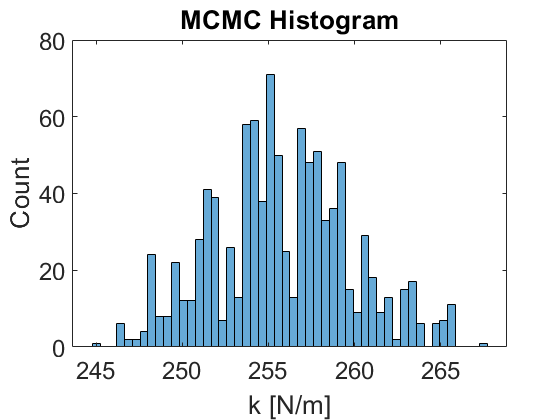

% This is to plot the histogram of the samples obtained via MCMC:
figure;
nbins=50; % Number of bins for the histogram
histogram(samples_mcmc,nbins); 
title('MCMC Histogram')
xlabel('k [N/m]','Fontsize',20);
ylabel('Count','Fontsize',20);
set(gca,'FontSize',18)


mcmc_mean_k = mean(samples_mcmc(:,1)); % To calcuate the sample mean
mcmc_std_k = std(samples_mcmc(:,1));   % To calculate the sample standard deviation

fprintf('Estimated k via MCMC: %4.2f with standard deviation: %4.2f. \n',mcmc_mean_k,mcmc_std_k)

Estimated k via MCMC: 255.80 with standard deviation: 4.02. 


% To display in the Command Window the mean and standard deviation of k obtained via the MCMC sampler.

Percentage_error_mcmc = (mcmc_std_k./mcmc_mean_k)*100; % To calculate the percentage error of the estimation

fprintf('The percentage error of the estimation of k via MCMC is: %3.2f%% \n', Percentage_error_mcmc)

The percentage error of the estimation of k via MCMC is: 1.57% 


% To display in the Command Window the percentage error of the estimation of k obtained by the MCMC sampler.

As a check for convergence of the samples, a Time-series plot can be plotted to observe the sample values obtained for $k$. This can be used to observe the convergence of the sample values with respect to its mean value as well as its associated uncertainty ($1$ standard deviation). 

% Compute cumulative mean and variance for MCMC samples:
dim=1; 

samples_mcmc =   250.3916
  250.3916
  259.8581
  259.8581
  259.8581
  253.6150
  251.6482
  251.6482
  251.6482
  251.6482


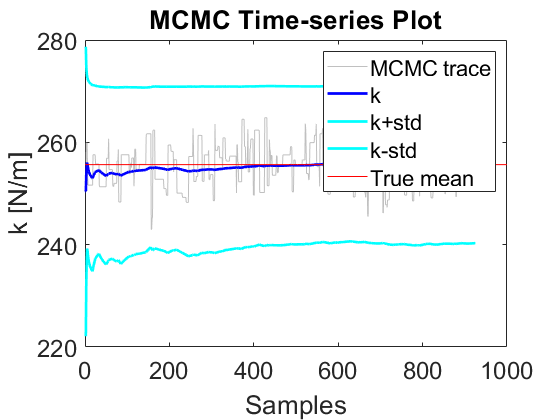


for n=1:size(samples_mcmc,2)
% Note: size(samples_mcmc,2) accounts for the dimension number of the samples.

% Transpose matrix of samples for counting as a function of number of sample:
samples_mcmcT=transpose(squeeze(samples_mcmc(:,n,:)));

allSamples=samples_mcmc(1:numel(samples_mcmcT));

if isrow(allSamples)
    allSamples=transpose(allSamples);
end

cumcountMCMC = 1:size(allSamples,dim);

cummeanMCMC = bsxfun(@rdivide, cumsum(allSamples)', cumcountMCMC);
cumvarMCMC = bsxfun(@rdivide, cumsum((allSamples - mcmc_mean_k).^2)', (cumcountMCMC-1));
cumstdMCMC = sqrt(cumvarMCMC);

% This is to plot the Time-series plot of samples obtained via MCMC:
figure;
p1=plot(cumcountMCMC,allSamples);
p1.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountMCMC,cummeanMCMC,'LineWidth',2,"Color",'b');
plot(cumcountMCMC,cummeanMCMC+cumstdMCMC,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountMCMC,cummeanMCMC-cumstdMCMC,'LineWidth',2,"LineStyle","-","Color",'c');
mu1 = mean(samples_mcmc(:,1));
hline = refline([0 mu1]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('MCMC Time-series Plot')
xlim([0, 925])
legend('MCMC trace','k','k+std','k-std','True mean')
xlabel('Samples','Fontsize',20);
ylabel('k [N/m]','Fontsize',20);
set(gca,'FontSize',18)
hold off;
end

### 4.1.4) MCMC Model Update

This is to plot the updated model from the MCMC results.

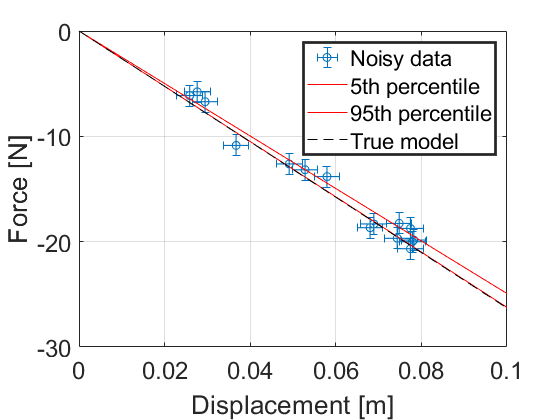

% Calculate results from the model:
disp=linspace(0,0.1,50);
bounds_mcmc = prctile(samples_mcmc, [5, 95]);
MCMCLowerBound = MyModel(bounds_mcmc(1),disp);
MCMCUpperBound = MyModel(bounds_mcmc(2),disp);
True_model = MyModel(k,disp);
figure;
h1 = errorbar(displacements,Measurements,y_err,y_err,x_err,x_err,'o','LineWidth',0.8);
box on
grid on
hold on
plot(disp,MCMCLowerBound,'r')
plot(disp,MCMCUpperBound,'r')
legend('Noisy data','5th percentile','95th percentile','LineWidth',2)
plot(disp,True_model,'k--','DisplayName','True model')
xlabel('Displacement [m]','FontSize',20)
ylabel('Force [N]','FontSize',20)
set(gca,'FontSize',18)
hold off

### 4.2) Transitional Markov Chain Monte Carlo (TMCMC)

TMCMC is a sampling method which obtains samples through "Transitional" distributions, $P_j$, instead of obtaining samples directly from the Posterior distribution itself. These "Transitional" distributions are defined as such:


$$P_j \propto P(D|\mathbf{\theta})^{\beta_j} \cdot P(\mathbf{\theta})$$


whereby $j$ denotes the iteration number, and $\beta_j$ is the scaling factor such that $0 = \beta_0 < \beta_1<...<\beta_{m-1}<\beta_m=1$with $m$ denoting the last iteration number. As such, the TMCMC sampler works by sampling from the Prior distribution, $P_0 \propto P(\mathbf{\theta})$, at the initial stage ($j=0$), and then obtaining samples from the intermediate "Transitional" distributions through the iterations before finally obtaining samples from the Posterior, $P_m \propto P(\mathbf{\theta}|D)$, at the very last iteration ($j=m$).

This method is particularly useful especially when sampling from a Posterior whose distribution function is complicated, such as having multiple nodes or has a high number of dimensions. More information can be found in the literature by [Ching and Chen (2007)](https://ascelibrary.org/doi/10.1061/%28ASCE%290733-9399%282007%29133%3A7%28816%29). Details to the algorithm can be found in Algorithm 4 of the tutorial paper.

To initiate the TMCMC sampler, the number of samples (Nsamples_tmcmc) to obtain from the Posterior distribution, $P(\mathbf{\theta}|D)$, is to be defined.

% Defining the variables: 
Nsamples_tmcmc = 1000;     % Number of samples to be obtained from the Posterior.

#### 4.2.1) Initiate and Execute the TMCMC sampler

The TMCMC sampler is executed by calling out the external TMCMC function handle which can be found in the file titled: "TMCMCsampler.m".

tic; % To commence the timer.

% To initiate the TMCMC sampler:
samples_tmcmc = TMCMCsampler('nsamples',Nsamples_tmcmc,'loglikelihood',log_l,'priorpdf',prior_pdf,...
              'priorrnd',rnd_k,'burnin',0,'lastburnin',0);

TMCMC: Iteration j =  1, pj1 = 0.000769
Computing the weights ...
Markov chains ...


TMCMC: Iteration j =  2, pj1 = 0.006545
Computing the weights ...
Markov chains ...


TMCMC: Iteration j =  3, pj1 = 0.046479
Computing the weights ...
Markov chains ...


TMCMC: Iteration j =  4, pj1 = 0.364780
Computing the weights ...
Markov chains ...


TMCMC: Iteration j =  5, pj1 = 1.000000
Computing the weights ...
Markov chains ...





timeTMCMC=toc; % To stop the timer.

fprintf('Time elapsed is for the TMCMC sampler: %f \n',timeTMCMC)

Time elapsed is for the TMCMC sampler: 10.104921 


% To display in the Command Window that the time elapsed refers to the time
% taken for the TMCMC sampler to obtain samples.

#### 4.2.2) Analysis of the samples obtained via TMCMC sampler

A histogram is plotted to illustrate the distribution of the samples that is obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$.

Use the histogram plot is fitted with a Normal distribution function given its distribution profile and this can be done using the [histfit](https://uk.mathworks.com/help/stats/histfit.html) function.

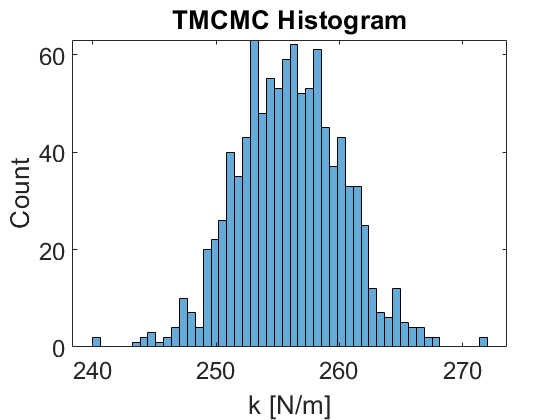

% This is to plot the histogram of the samples obtained via TMCMC:
figure;
nbins=50; % Number of bins for the histogram
histogram(samples_tmcmc,nbins); 
title('TMCMC Histogram')
xlabel('k [N/m]','Fontsize',20);
ylabel('Count','Fontsize',20);
set(gca,'FontSize',18)


tmcmc_mean_k = mean(samples_tmcmc(:,1)); % To calculate sample mean
tmcmc_std_k = std(samples_tmcmc(:,1));   % To calculate sample standard deviation

fprintf('Estimated k via TMCMC: %4.2f with standard deviation: %4.2f. \n',tmcmc_mean_k,tmcmc_std_k)

Estimated k via TMCMC: 256.01 with standard deviation: 4.26. 


% To display in the Command Window the mean and standard deviation of k obtained via the TMCMC sampler.

Percentage_error_tmcmc = (tmcmc_std_k./tmcmc_mean_k)*100; % To calculate the percentage error of the estimation

fprintf('The percentage error of the estimation of k via TMCMC is: %3.2f%% \n', Percentage_error_tmcmc)

The percentage error of the estimation of k via TMCMC is: 1.66% 


% To display in the Command Window the percentage error of the estimation of k obtained by the TMCMC sampler.

As a check for convergence of the samples, a Time-series plot can be plotted to observe the sample values obtained for $k$. This can be used to observe the convergence of the sample values with respect to its mean value as well as its associated uncertainty ($1$ standard deviation). 

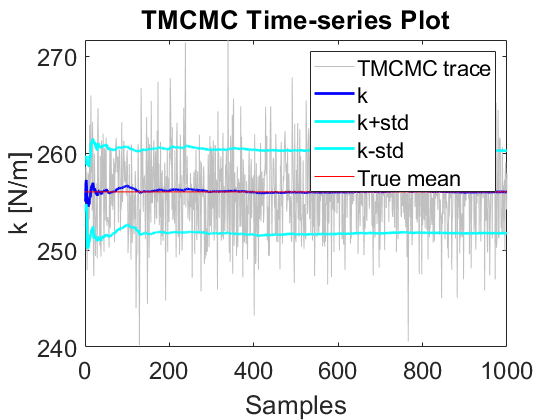

% Compute cumulative mean and variance for TMCMC samples:
dim=1; 
cumcountTMCMC = 1:size(samples_tmcmc,dim);

cummeanTMCMC = bsxfun(@rdivide, cumsum(samples_tmcmc)', cumcountTMCMC);
cumvarTMCMC = bsxfun(@rdivide, cumsum((samples_tmcmc - tmcmc_mean_k).^2)', (cumcountTMCMC-1));
cumstdTMCMC = sqrt(cumvarTMCMC);

% This is to plot the Time-series plot of samples obtained via TMCMC:
figure(6);
p2=plot(cumcountTMCMC,samples_tmcmc);
p2.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountTMCMC,cummeanTMCMC,'LineWidth',2,"Color",'b');
plot(cumcountTMCMC,cummeanTMCMC+cumstdTMCMC,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountTMCMC,cummeanTMCMC-cumstdTMCMC,'LineWidth',2,"LineStyle","-","Color",'c');
mu2 = mean(samples_tmcmc(:,1));
hline = refline([0 mu2]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('TMCMC Time-series Plot')
legend('TMCMC trace','k','k+std','k-std','True mean')
xlabel('Samples','Fontsize',20);
ylabel('k [N/m]','Fontsize',20);
set(gca,'FontSize',18)
hold off;

### 4.2.3) TMCMC Model Update

This is to plot the updated model from the TMCMC results.

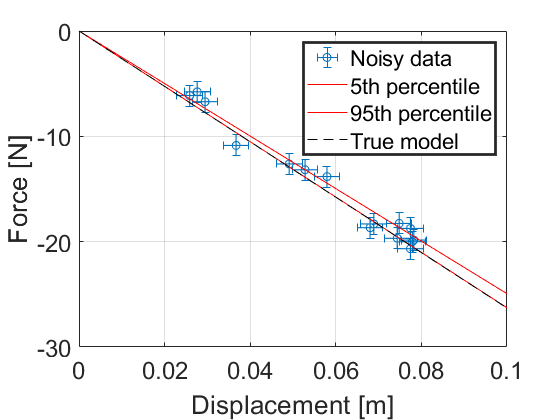

% Calculate results from the model:
disp=linspace(0,0.1,50);
bounds_tmcmc = prctile(samples_tmcmc, [5, 95]);
TMCMCLowerBound = MyModel(bounds_tmcmc(1),disp);
TMCMCUpperBound = MyModel(bounds_tmcmc(2),disp);
True_model = MyModel(k,disp);
figure;
h1 = errorbar(displacements,Measurements,y_err,y_err,x_err,x_err,'o','LineWidth',0.8);
box on
grid on
hold on
plot(disp,TMCMCLowerBound,'r')
plot(disp,TMCMCUpperBound,'r')
legend('Noisy data','5th percentile','95th percentile','LineWidth',2)
plot(disp,True_model,'k--','DisplayName','True model')
xlabel('Displacement [m]','FontSize',20)
ylabel('Force [N]','FontSize',20)
set(gca,'FontSize',18)
hold off

### 4.3) Sequential Monte Carlo (SMC)

The SMC sampler adopts a recursive sampling algorithm that is based on the Sequential Monte Carlo method (also known as [Particle Filters](https://www.jstor.org/stable/2669847?seq=1#metadata_info_tab_contents)) and it is particularly useful in addressing Bayesian updating problems involving large data sets. An advantage of the SMC sampler is that it can be used to sample from static and dynamical Target distributions. It utilises two main sampling methods in its algorithm: Importance sampling, and Re-sampling. More details can be found in the literatures by [Moral et. al](https://www.jstor.org/stable/3879283?seq=1#metadata_info_tab_contents) and [Green et. al](https://www.sciencedirect.com/science/article/pii/S0888327016305520). Details to the algorithm can be found in Algorithm 7 of the tutorial paper.

To initiate the sampler, there are 3 parameters that need to be defined: the number of samples to obtain from the Posterior distribution (Nsamples_smc), the Tuning-parameter (Tuning_smc), and the Number of Iterations of the sampler (no_iterations). 

The number of samples (Nsamples_smc) parameter defines the sample size to be obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$.

The Tuning-parameter (Tuning_smc) corresponds to the standard deviation of the Gaussian Proposal distribution that is defined within the SMC sampler algorithm. The choice of the Tuning-parameter would in turn have an effect on the convergence level of the samples.

The Number of Iterations (no_iterations) refers to the number of times the recursive algorithms is to run. In this problem, as we are sampling from a static Posterior distribution, $P(\mathbf{\theta}|D)$, this value can be set to 1.

% Defining the variables: 
Nsamples_smc = 1000; % Number of samples to be obtained.

Tuning_smc = 1.5;   % The tuning parameter for SMC sampler.

no_iterations = 1;    % The user-defined number of iterations for the SMC sampler.

#### 4.2.1) Initiate and Execute the SMC sampler

The SMC sampler is executed by calling out the external SMC function handle which can be found in the file titled: "SMCsampler.m".

tic; % To commence the timer.

% To initiate the SMC sampler:
smc = SMCsampler('nsamples', Nsamples_smc,...
'prior_values', rnd_k(Nsamples_smc),... 
'prior', prior_pdf, 'loglikelihood', log_l, 'no_iterations', no_iterations,...
'prop_covariance', Tuning_smc);
smc = smc.generate_samples();      % To generate samples from the SMC sampler
samples_smc = smc.theta;           % To obtain the SMC samples

timeSMC = toc; % To stop the timer.

fprintf('Time elapsed is for the SMC sampler: %f \n',timeSMC)

Time elapsed is for the SMC sampler: 0.640037 


% To display in the Command Window that the time elapsed refers to the time
% taken for the SMC sampler to obtain samples.

#### 4.2.2) Analysis of the samples obtained via SMC sampler

A histogram is plotted to illustrate the distribution of the samples that is obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$.

Use the histogram plot is fitted with a Normal distribution function given its distribution profile and this can be done using the [histfit](https://uk.mathworks.com/help/stats/histfit.html) function.

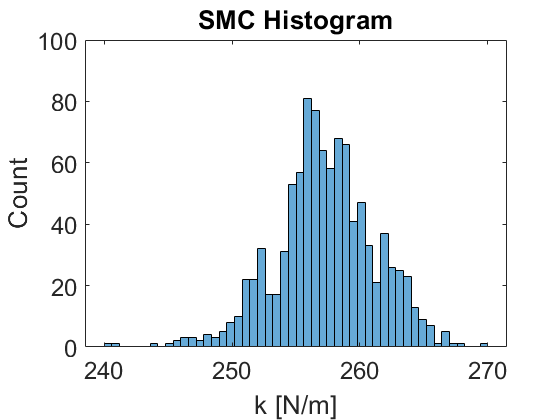

% This is to plot the histogram of the samples obtained via SMC:
figure;
nbins=50; % Number of bins for the histogram
histogram(samples_smc,nbins); 
title('SMC Histogram')
xlabel('k [N/m]','Fontsize',20);
ylabel('Count','Fontsize',20);
set(gca,'FontSize',18)


smc_mean_k = mean(samples_smc(:,1)); % To calculate sample mean
smc_std_k = std(samples_smc(:,1));   % To calculate sample standard deviation

fprintf('Estimated k via SMC: %4.2f with standard deviation: %4.2f. \n',smc_mean_k,smc_std_k)
% To display in the Command Window the mean and standard deviation of k obtained via the SMC sampler.


Estimated k via SMC: 257.33 with standard deviation: 3.88. 


Percentage_error_smc = (smc_std_k./smc_mean_k)*100;

fprintf('The percentage error of the estimation of k via SMC is: %3.2f%% \n', Percentage_error_smc)

The percentage error of the estimation of k via SMC is: 1.51% 


% To display in the Command Window the percentage error of the estimation of k obtained by the SMC sampler.

As a check for convergence of the samples, a Time-series plot can be plotted to observe the sample values obtained for $k$. This can be used to observe the convergence of the sample values with respect to its mean value as well as its associated uncertainty ($1$ standard deviation). 

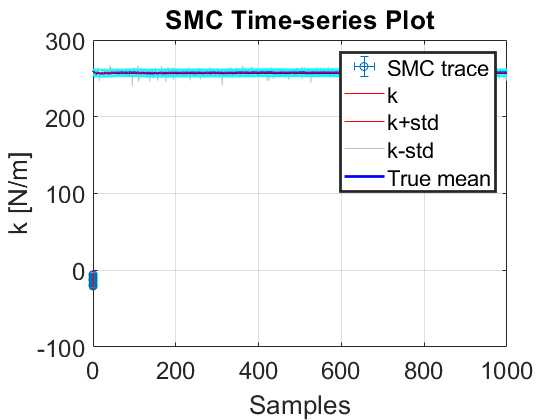

% Compute cumulative mean and variance for SMC samples:
dim=1; 
cumcountSMC = 1:size(samples_smc,dim);

cummeanSMC = bsxfun(@rdivide, cumsum(samples_smc)', cumcountSMC);
cumvarSMC = bsxfun(@rdivide, cumsum((samples_smc - smc_mean_k).^2)', (cumcountSMC-1));
cumstdSMC = sqrt(cumvarSMC);

% This is to plot the Time-series plot of samples obtained via SMC:
figure(8);
p3=plot(cumcountSMC,samples_smc);
p3.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountSMC,cummeanSMC,'LineWidth',2,"Color",'b');
plot(cumcountSMC,cummeanSMC+cumstdSMC,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountSMC,cummeanSMC-cumstdSMC,'LineWidth',2,"LineStyle","-","Color",'c');
mu3 = mean(samples_smc(:,1));
hline = refline([0 mu3]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('SMC Time-series Plot')
legend('SMC trace','k','k+std','k-std','True mean')
xlabel('Samples','Fontsize',20);
ylabel('k [N/m]','Fontsize',20);
set(gca,'FontSize',18)
hold off;

### 4.2.3) SMC Model Update

This is to plot the updated model from the SMC results.

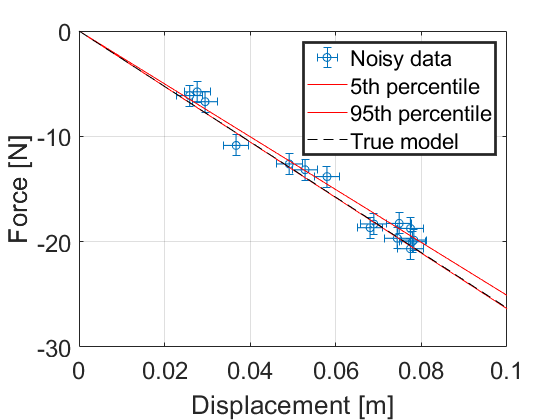

% Calculate results from the model:
disp=linspace(0,0.1,50);
bounds_smc = prctile(samples_smc, [5, 95]);
SMCLowerBound = MyModel(bounds_smc(1),disp);
SMCUpperBound = MyModel(bounds_smc(2),disp);
True_model = MyModel(k,disp);
figure;
h1 = errorbar(displacements,Measurements,y_err,y_err,x_err,x_err,'o','LineWidth',0.8);
box on
grid on
hold on
plot(disp,SMCLowerBound,'r')
plot(disp,SMCUpperBound,'r')
legend('Noisy data','5th percentile','95th percentile','LineWidth',2)
plot(disp,True_model,'k--','DisplayName','True model')
xlabel('Displacement [m]','FontSize',20)
ylabel('Force [N]','FontSize',20)
set(gca,'FontSize',18)
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% End of Code %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%